data = readtable("OneDrive_1_16-02-2024/Speedtest Results (CSV Export)");


%ms
meanJitter_4G = mean(data{1:5,"Jitter"})

meanJitter_4G = 15

meanJitter_5G = mean(data{6:10, "Jitter"})

meanJitter_5G = 2.6000

Jitter = [meanJitter_4G, meanJitter_5G];

%Mbps
meanDL_Speed_4G = mean(data{1:5,"DownloadSpeed"})

meanDL_Speed_4G = 68.5591

meanDL_Speed_5G = mean(data{6:10, "DownloadSpeed"})

meanDL_Speed_5G = 518.2122

DL_Speed = [meanDL_Speed_4G, meanDL_Speed_5G];

%Mb
meanDL_Size_4G = mean(data{1:5, "DownloadSize"})/(10^6)

meanDL_Size_4G = 95.7343

meanDL_Size_5G = mean(data{6:10, "DownloadSize"})/(10^6)

meanDL_Size_5G = 722.6897

DL_Size = [meanDL_Size_4G, meanDL_Size_5G];
%Mbps
meanUL_Speed_4G = mean(data{1:5,"UploadSpeed"})

meanUL_Speed_4G = 13.7115

mean_UL_Speed_5G = mean(data{6:10, "UploadSpeed"})

mean_UL_Speed_5G = 8.1786

UL_Speed = [meanUL_Speed_4G, mean_UL_Speed_5G];

%Mb
meanUL_Size_4G = mean(data{1:5, "UploadSize"})/(10^6)

meanUL_Size_4G = 8.3950

meanUL_Size_5G = mean(data{6:10,"UploadSize"})/(10^6)

meanUL_Size_5G = 11.5646

UL_Size = [meanUL_Size_4G, meanUL_Size_5G];

%ms
mean_Latency_4G = mean(data{1:5,"Latency"})

mean_Latency_4G = 18.6000

mean_Latency_5G = mean(data{6:10,"Latency"})

mean_Latency_5G = 12.2000

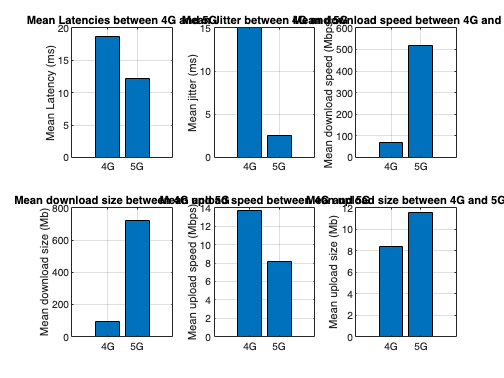

Latency = [mean_Latency_4G, mean_Latency_5G];

figure;
subplot(2,3,1)
bar(Latency)
title('Mean Latencies between 4G and 5G')
ylabel('Mean Latency (ms)')
xticklabels({'4G', '5G'})
grid on

subplot(2,3,2)
bar(Jitter)
title('Mean Jitter between 4G and 5G')
ylabel('Mean jitter (ms)')
xticklabels({'4G', '5G'})
grid on

subplot(2,3,3)
bar(DL_Speed)
title('Mean download speed between 4G and 5G')
ylabel('Mean download speed (Mbps)')
xticklabels({'4G', '5G'})
grid on

subplot(2,3,4)
bar(DL_Size)
title('Mean download size between 4G and 5G')
ylabel('Mean download size (Mb)')
xticklabels({'4G', '5G'})
grid on

subplot(2,3,5)
bar(UL_Speed)
title('Mean upload speed between 4G and 5G')
ylabel('Mean upload speed (Mbps)')
xticklabels({'4G', '5G'})
grid on

subplot(2,3,6)
bar(UL_Size)
title('Mean upload size between 4G and 5G')
ylabel('Mean upload size (Mb)')
xticklabels({'4G', '5G'})
grid on

clear;
first_floor = readtable("OneDrive_1_16-02-2024/2024-02-16-14-47-26-0000-0000-5683-4953-S.csv");

second_floor = readtable("OneDrive_1_16-02-2024/2024-02-16-14-55-52-0000-0000-5683-4953-S.csv");

library = readtable("OneDrive_1_16-02-2024/2024-02-16-15-03-48-0000-0000-5683-4953-S.csv");

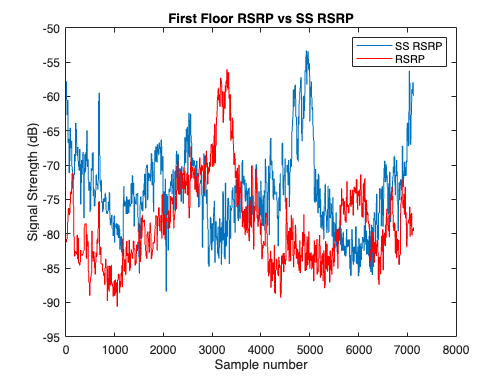

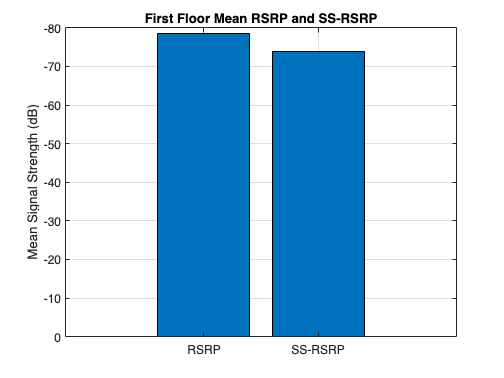

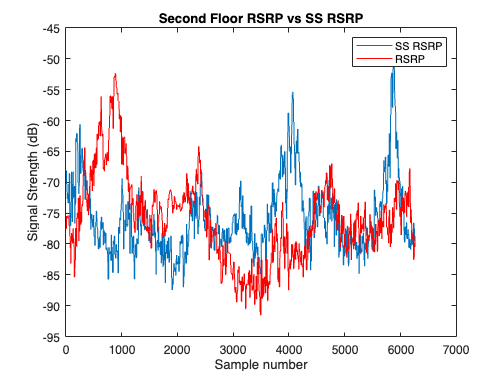

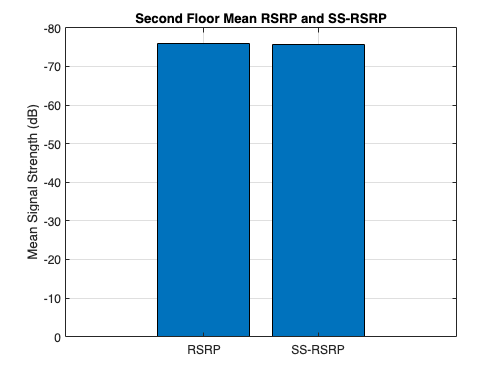

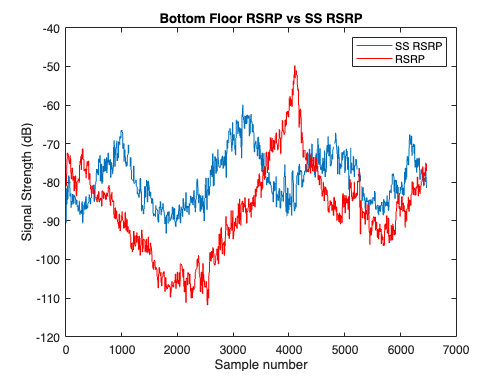

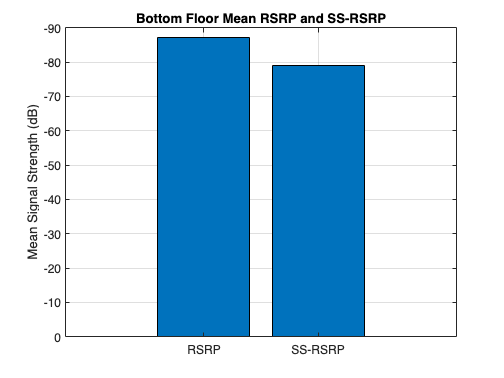

names = {'First Floor', 'Second Floor', 'Bottom Floor'};
floors = {first_floor, second_floor, library};
for i=1:3
    name = names{i};
    floor = floors{i};
    visualize(floor, name)
end

function visualize(data, name)
    ssrsrp_mean = mean(data.SS_RSRP__PCell_, 'omitnan');
    rsrp_mean = mean(data.RSRP__PCell_,'omitnan');
    m = [rsrp_mean ssrsrp_mean];
    figure
    plot(data,"SS_RSRP__PCell_")
    hold on
    plot(data,"RSRP__PCell_",'Color','r')
    hold off 
    legend('SS RSRP', 'RSRP')
    ylabel('Signal Strength (dB)')
    xlabel('Sample number')
    title(sprintf('%s RSRP vs SS RSRP', name))
    figure
    bar(m)
    set(gca, 'YDir', 'reverse')
    xticklabels({'RSRP', 'SS-RSRP'})
    ylabel('Mean Signal Strength (dB)')
    title(sprintf('%s Mean RSRP and SS-RSRP', name))
    grid on
end


